## Definitions of constants/variables

%Resetting the rng seed
rng("default");
rng(1960);
symbol_num = 10000; 

%TODO create symbols of a known sequence for easier debugging

%symbols = importdata("const_rand_symbols.mat")'; %(Depricated)


symbols = randi([0 3],1,symbol_num);

known_symbols = zeros(1,symbol_num);

for i=1:symbol_num
    known_symbols(i) = mod(i,4);
end

%Known symbols are sent as 0,1,2,3,0,1,2,3...
%const_rand_sym_noise=importdata("const_rand_sym_noise.mat")';
symbol_rate = 100e9; %Hz
time_step = 1/symbol_rate; %seconds
linewidth = 100e3; %Hz
variance=2*pi*linewidth*time_step;
KNOWN = false;

## QPSK

if KNOWN
    modulated_symbols = pskmod(known_symbols,4,0,"gray");
else
    modulated_symbols = pskmod(symbols,4,0,'gray');
end

demod_symbols = pskdemod(modulated_symbols,4,0,'gray');

%%%Phase noise modeled as random walk%%%
%The cummulative sum of the standard deviations of each symbol's 
% phase as they are passed through the channel

phase_noise=randn(1,symbol_num);

sets = logspace(1,6,10);
sets_num = length(sets);

variances = (variance .* sets)';

phase_noise_sets = exp(1j*cumsum(sqrt(variances).*phase_noise));

%% Both phase and amplitude modified:
%phase_noise_sets = cumsum(sqrt(variances).*exp(1j*phase_noise));


noisy_modulated_symbols = modulated_symbols .* phase_noise_sets;

noisy_demod_symbols = pskdemod(noisy_modulated_symbols,4,0,"gray");


## Plotting QPSK output, after noise has been added

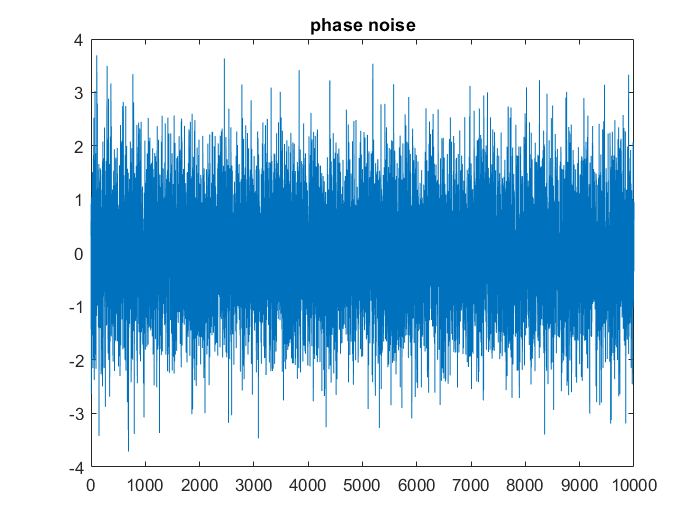

figure
plot(phase_noise)
title('phase noise')

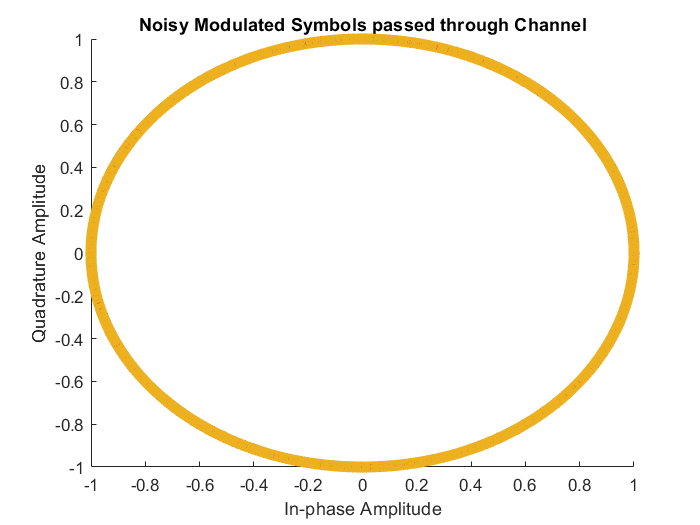


figure
for i=1:sets_num
hold on
scatter(real(noisy_modulated_symbols(i,:)),imag(noisy_modulated_symbols(i,:)));
end
title("Noisy Modulated Symbols passed through Channel")
xlabel("In-phase Amplitude")
ylabel("Quadrature Amplitude")
hold off

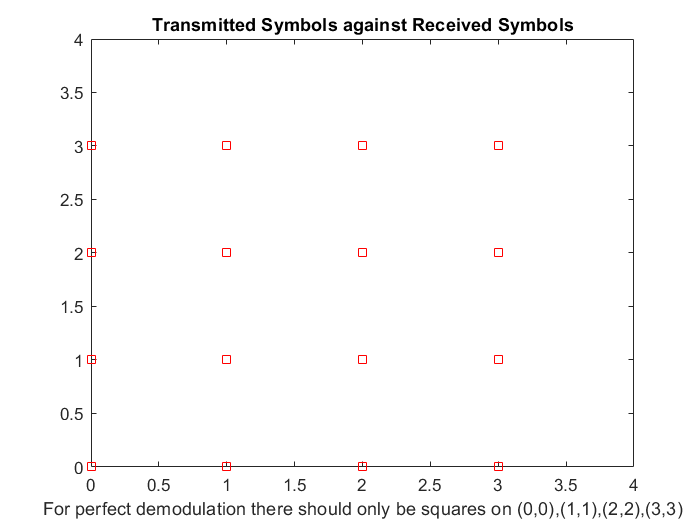

%{
figure
scatter(real(noisy_demod_symbols),imag(noisy_demod_symbols),"filled","d")
title("Demodulated Noisy Symbols 'passed' through Channel")
%}

figure
plot(noisy_demod_symbols,symbols,"rs")
title("Transmitted Symbols against Received Symbols")
xlabel("For perfect demodulation there should only be squares on (0,0),(1,1),(2,2),(3,3)")
%plot(modulated_symbols)
axis([0,4,0,4])

%grid on

## SNR and BER for Random Walk Phase Noise

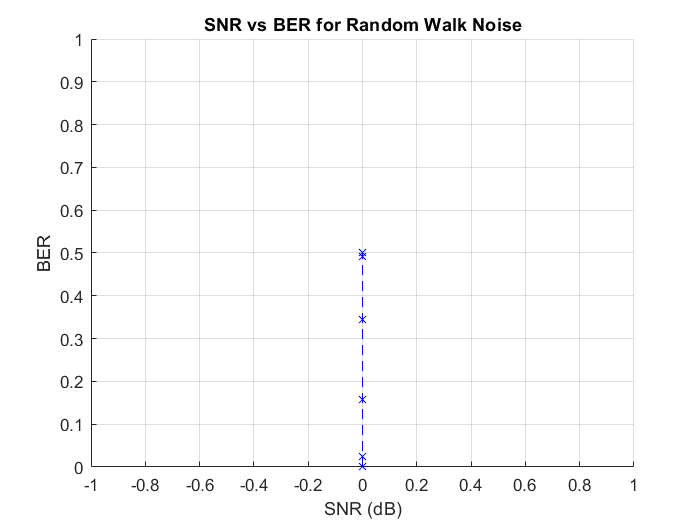

%This line initialises the arrays
[phase_noise_SNR,noisePow,num_of_errs,phase_noise_BER] = deal(zeros(sets_num,1));

figure
hold on
title("SNR vs BER for Random Walk Noise")
symbol_amplitude = abs(modulated_symbols);
noise_amplitude = abs(phase_noise_sets);

for i=1:sets_num
    phase_noise_SNR(i,:) = snr(symbol_amplitude,noise_amplitude(i,:)); %All in dB

    [num_of_errs(i,:),phase_noise_BER(i,:)] = biterr(symbols(1,:),noisy_demod_symbols(i,:),2);
end
plot(phase_noise_SNR,phase_noise_BER,"bx--")
grid on
xlabel("SNR (dB)")
ylabel("BER")
axis([-1,1,0,1])
hold off


%Since the noise is the same magnitude and only the phase component
%increases in each case, the SNR is continuously 0dB, while the BER
%increases.

## SNR and BER for AWGN

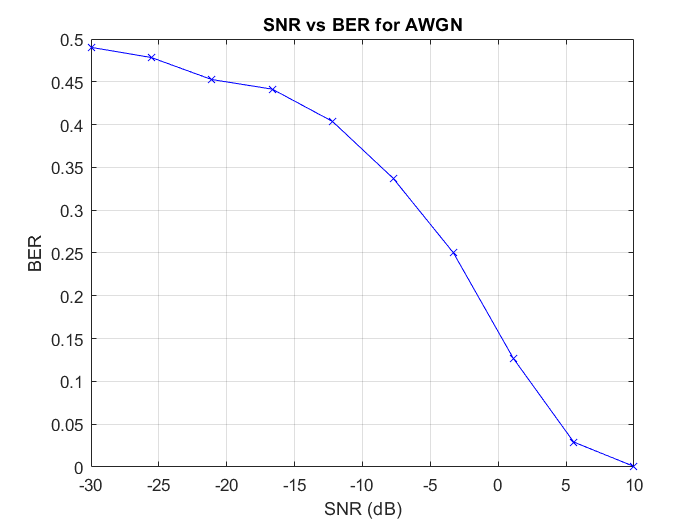

%%Correct Approach
%% SNR uses noise not noisy signals, fix sets
% awgn_symbols_1 = awgn(modulated_symbols,5);
% 
% plot(awgn_symbols_1,'.')
% 
% demoded_symbols = pskdemod(awgn_symbols_1,4,0,"gray")
% 
% plot(demoded_symbols,symbols,'.')
% measured_SNR = snr(abs(modulated_symbols),abs(awgn_symbols_1 - modulated_symbols))
% 
% [errs,BER] = biterr(symbols,demoded_symbols,2);
% 
% plot(measured_SNR,BER,"-rx")

snr_values = linspace(-30,10,sets_num);

awgn_symbols = zeros(sets_num,symbol_num);

for i=1:sets_num
    awgn_symbols(i,:) = awgn(modulated_symbols,snr_values(1,i));
end

%plot(awgn_symbols(10,:),'.')

awgn_demod_symbols = pskdemod(awgn_symbols,4,0,"gray");

awgn_noise_amplitude = abs(awgn_symbols-modulated_symbols);

for i=1:sets_num
    [AWGN_SNR(i),noisePow(i)] = snr(symbol_amplitude,awgn_noise_amplitude(i,:)); %All in dB
    [num_of_errs(i),AWGN_BER(i)] = biterr(symbols,awgn_demod_symbols(i,:),2);
end
figure
plot(AWGN_SNR,AWGN_BER,"-bx")
title("SNR vs BER for AWGN")
grid on
xlabel("SNR (dB)")
ylabel("BER")

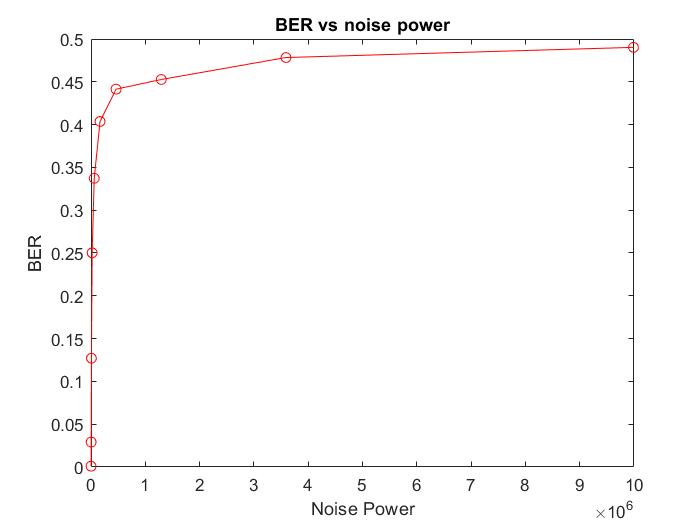

%axis([-1,1,0,1])


plot(noisePow,AWGN_BER,'-ro')
title("BER vs noise power")
xlabel("Noise Power")
ylabel("BER")

## Filtering/Oversampling

%{
symbol_rate = 100e9; 
time_step = 1/symbol_rate; 
linewidth = 100e3;
variance=2*pi*linewidth*time_step;}
%}

sampling=time_step/4;

oversampling = 4;
rrc_filter= rcosdesign(0.2,10,oversampling);
sampled_symbols = upfirdn(noisy_modulated_symbols',rrc_filter,oversampling);

%eyediagram(sampled_symbols(2:10000,1),oversampling);
%kron product

%scope = dsp.SpectrumAnalyzer(2);

%TO DO
% Modulate transceiver with raised cosine and match on receiver
%kroneker tensor product (for oversampling)
a=kron([1,2,3],[1,0,0,0])

a =      1     0     0     0     2     0     0     0     3     0     0     0


## Spectral Analysis

%noisy_modulated_symbols
%symbol_num
%symbol_rate
%time_step

%%Change the symbols to be a known frequency
hold off

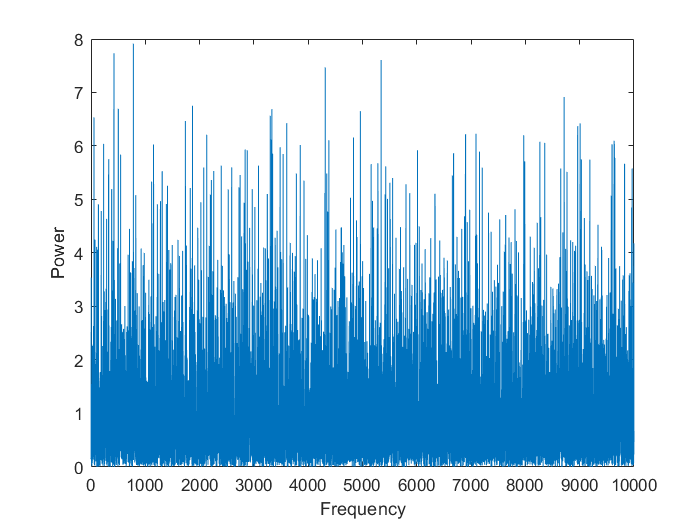

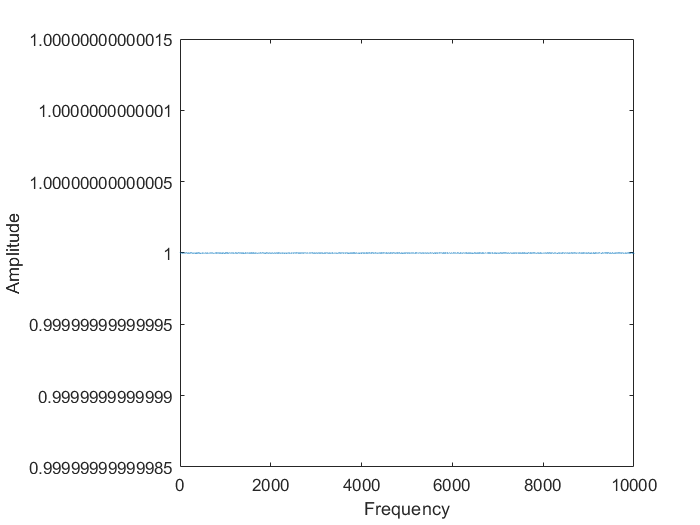

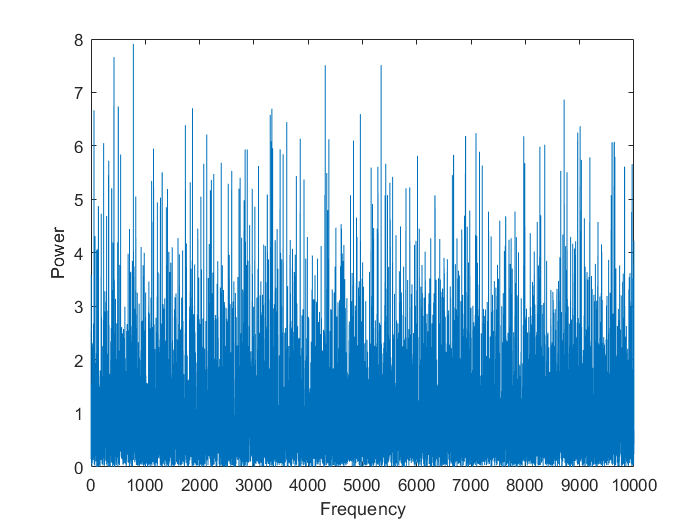

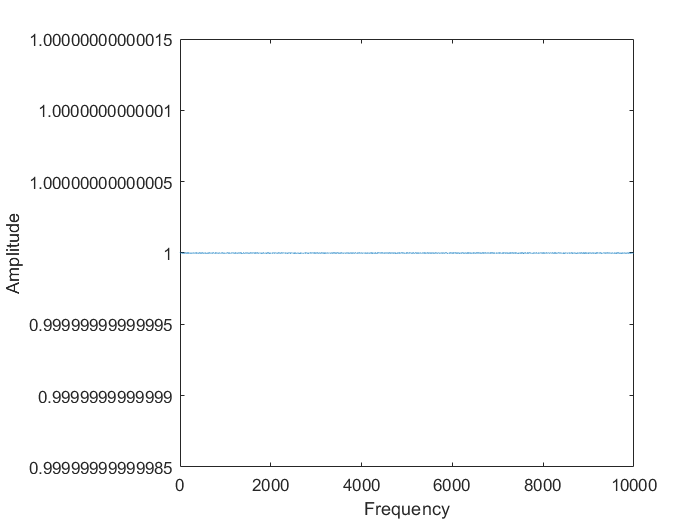

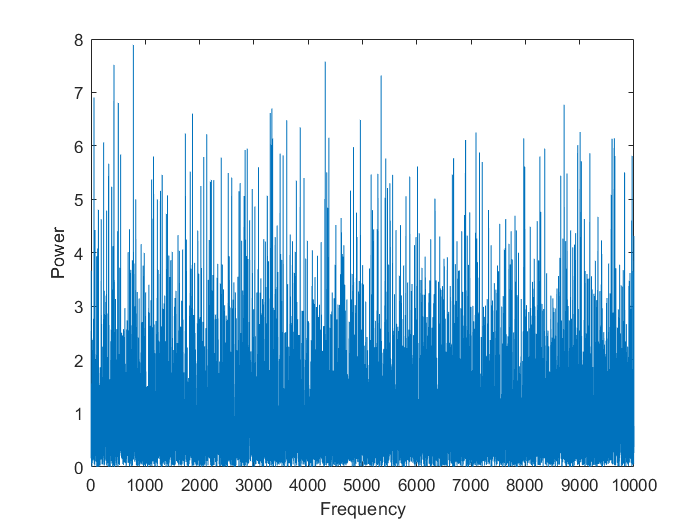

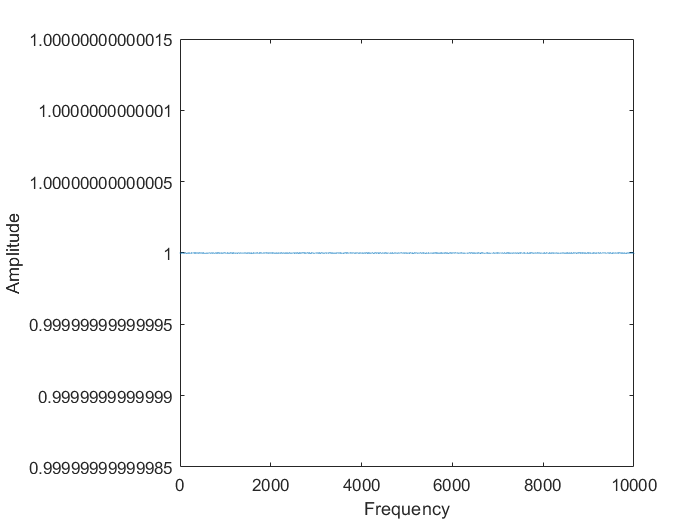

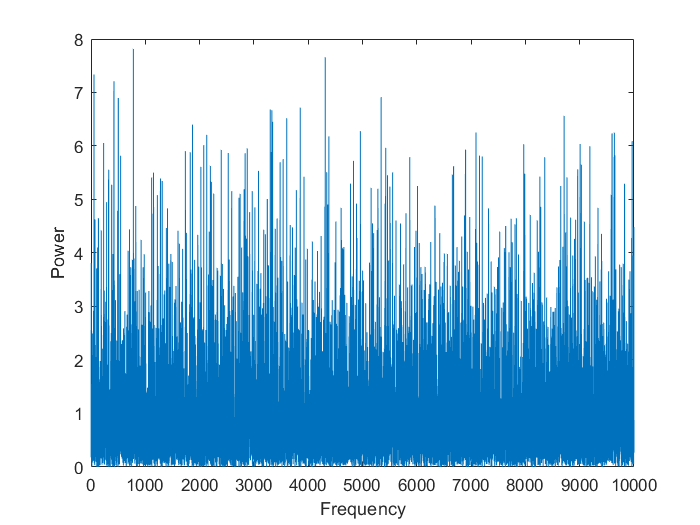

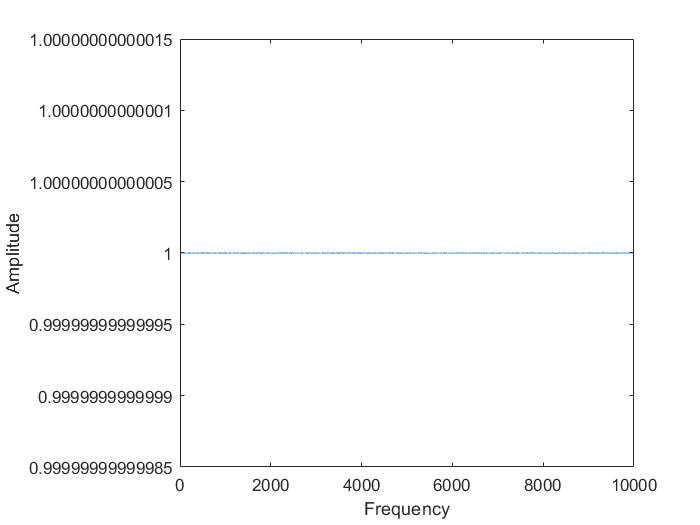

t = (0:symbol_num-1)/symbol_rate;
freq_inc = symbol_rate/symbol_num;
nyq_freq = symbol_rate/2;
y = zeros(sets_num,symbol_num);
amplitude = zeros(sets_num,symbol_num);
power = zeros(sets_num,symbol_num);

for i=1:size(noisy_modulated_symbols)
    y(i,:) = fft(noisy_modulated_symbols(i,:));
    amplitude(i,:) = abs(noisy_modulated_symbols(i,:));
    power(i,:) = (abs(y(i,:)).^2)/symbol_num;
end

for i=1:10
figure
plot(power(i,:));
xlabel("Frequency");
ylabel("Power");

figure
plot(amplitude(i,:));
xlabel("Frequency");
ylabel("Amplitude");
end


%Friday 13th presentation